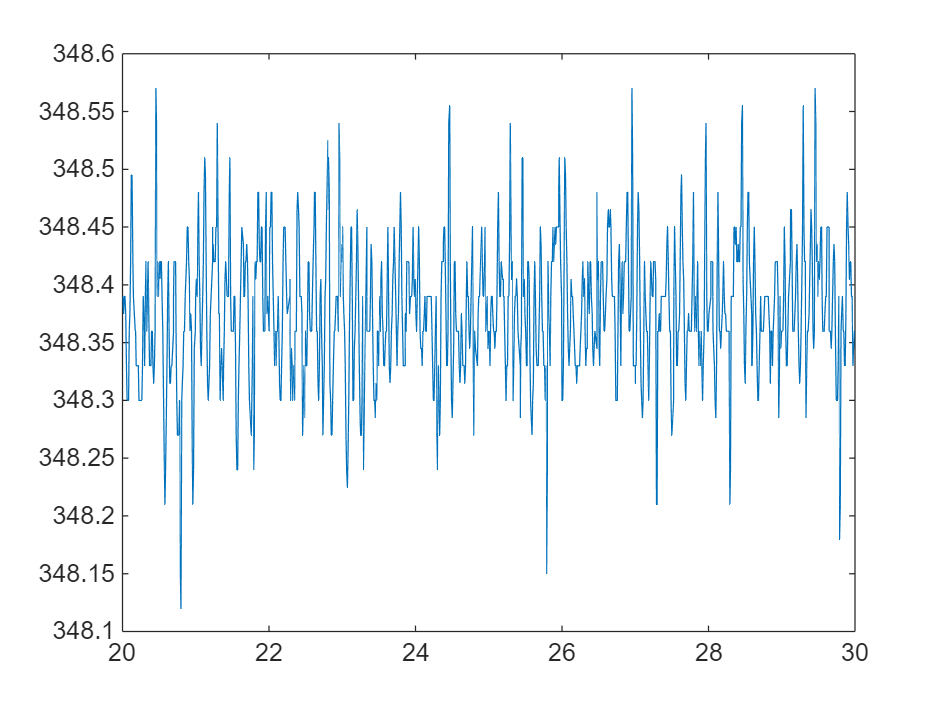

ts = 0.0096

std_ts = 0.0035

fs = 104.0729

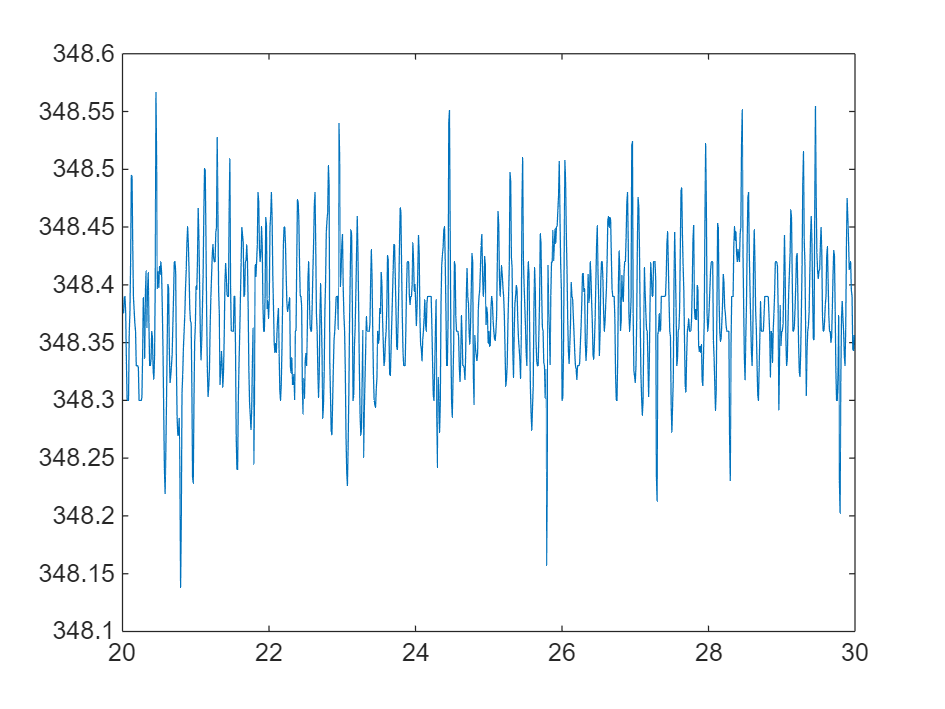

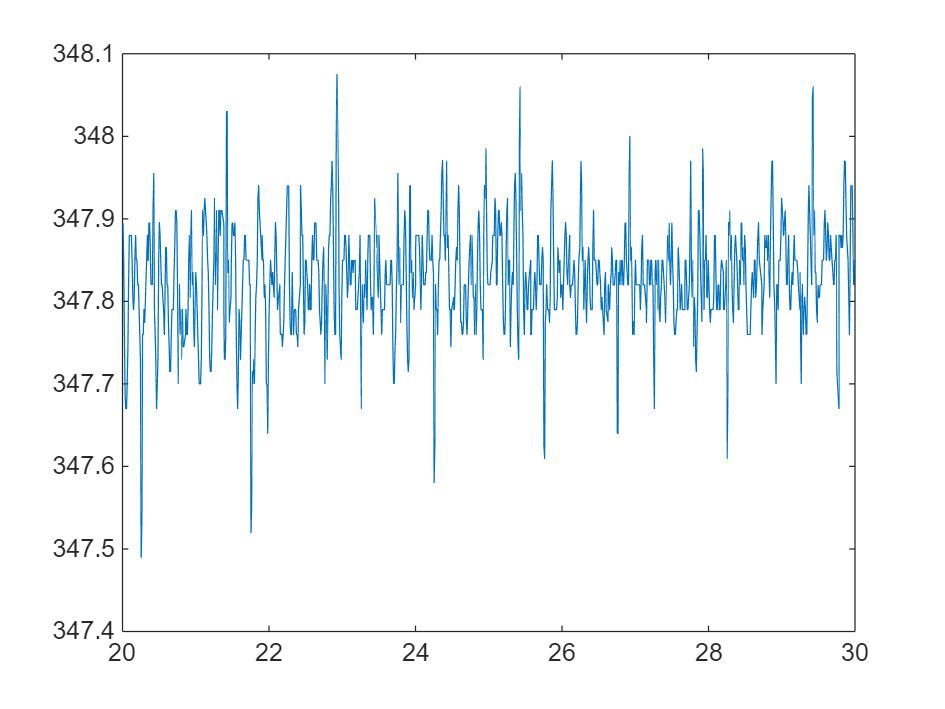

ts = 0.0096

std_ts = 0.0033

fs = 104.5673

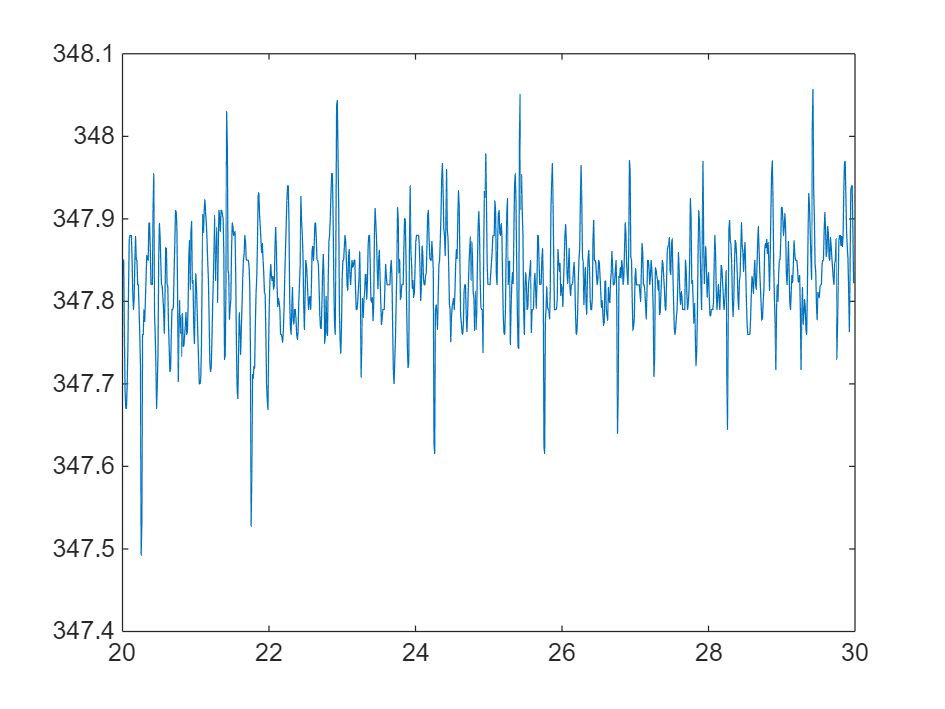

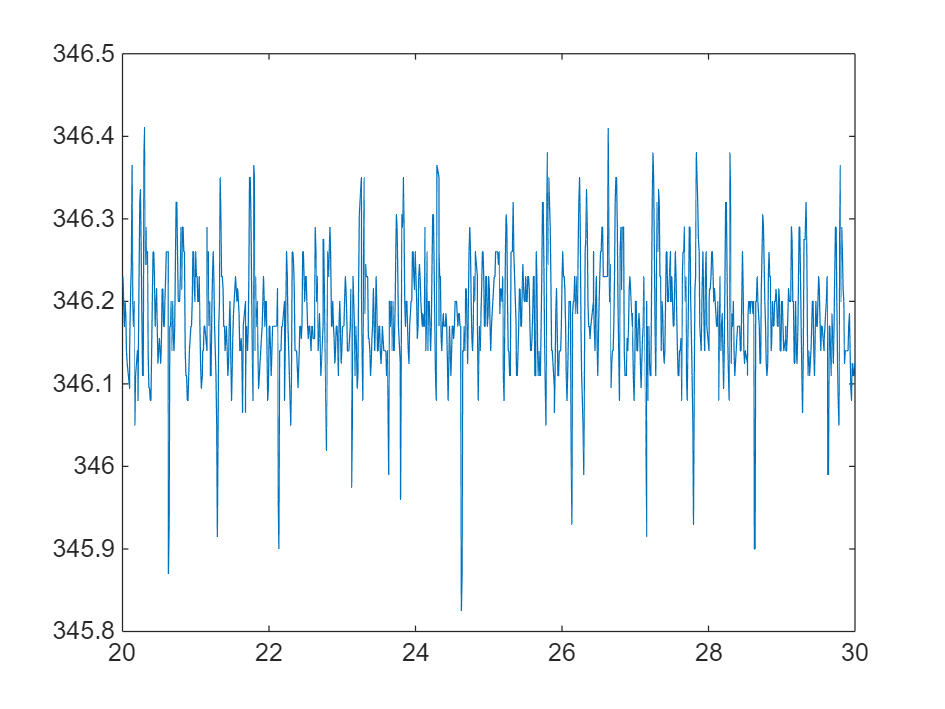

ts = 0.0096

std_ts = 0.0036

fs = 104.5673

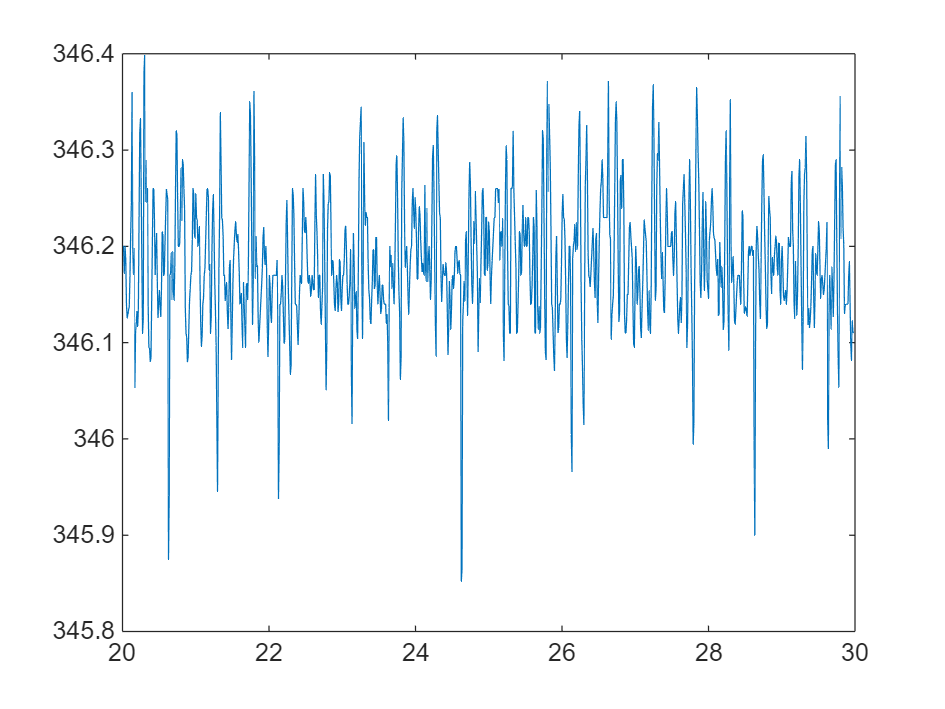

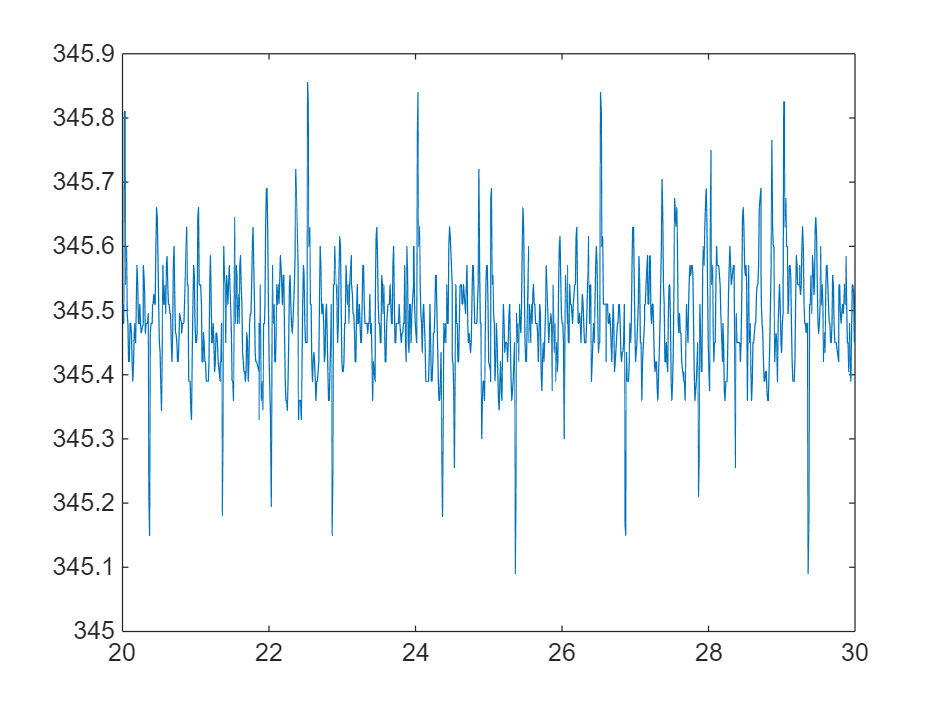

ts = 0.0097

std_ts = 0.0036

fs = 103.4655

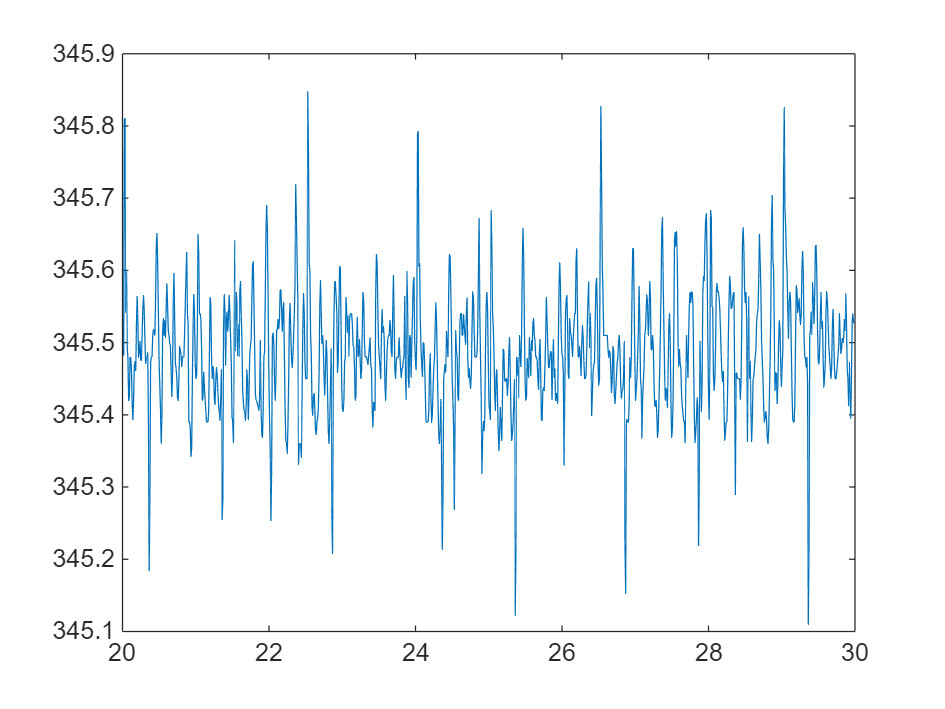

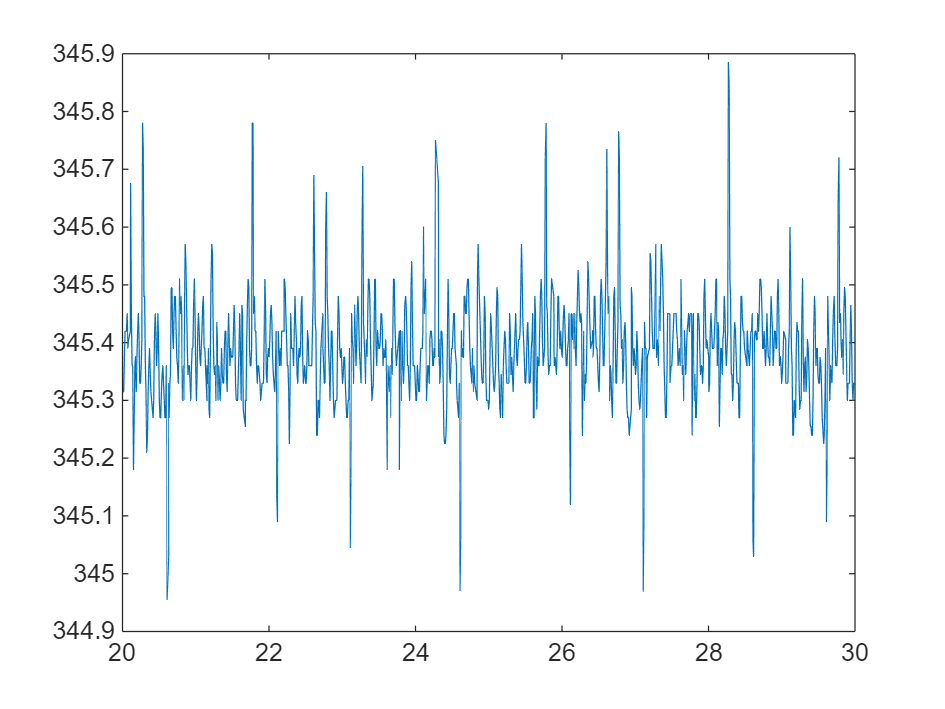

ts = 0.0096

std_ts = 0.0035

fs = 104.0561

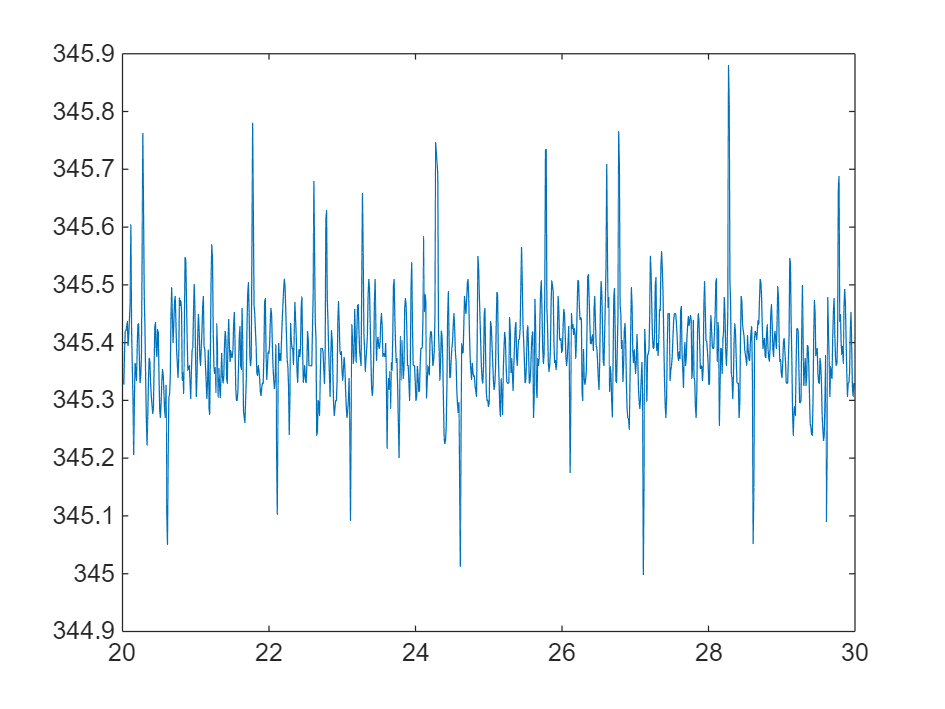

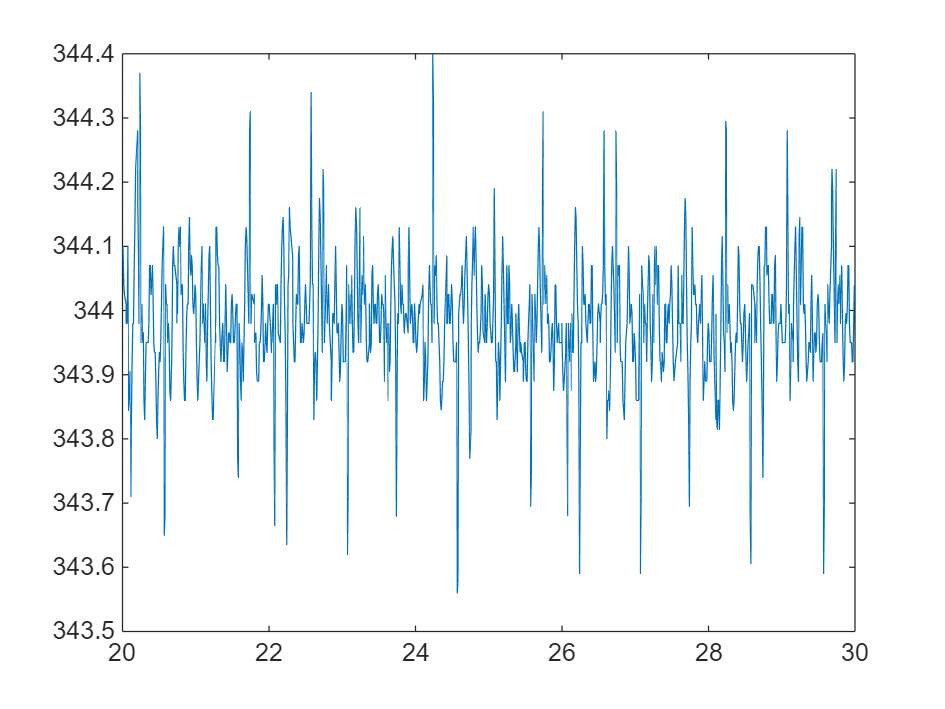

ts = 0.0096

std_ts = 0.0034

fs = 104.3670

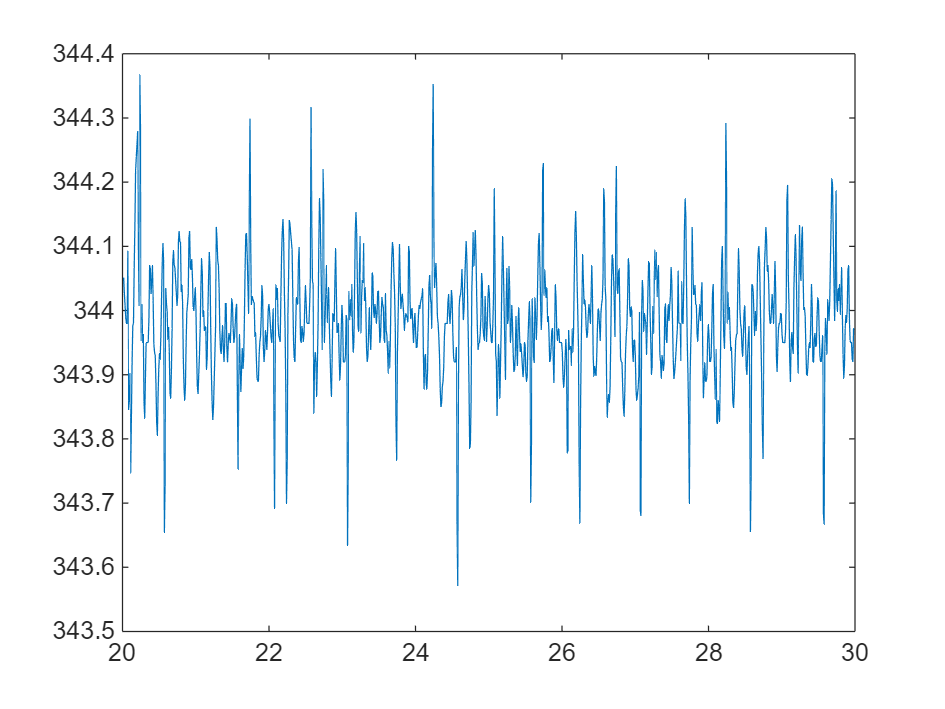

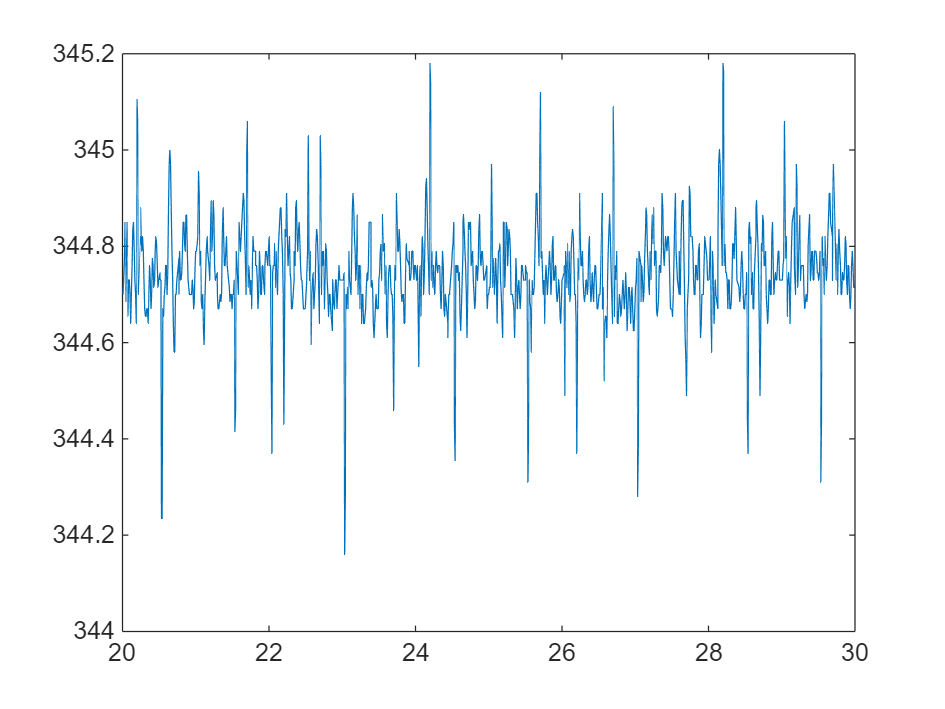

ts = 0.0096

std_ts = 0.0034

fs = 103.7660

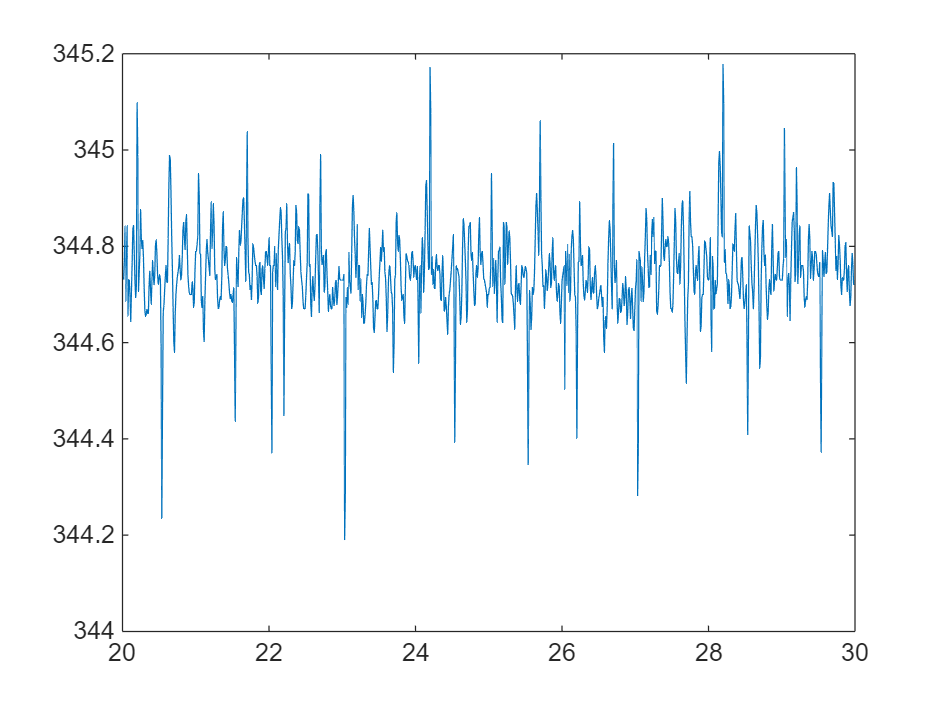

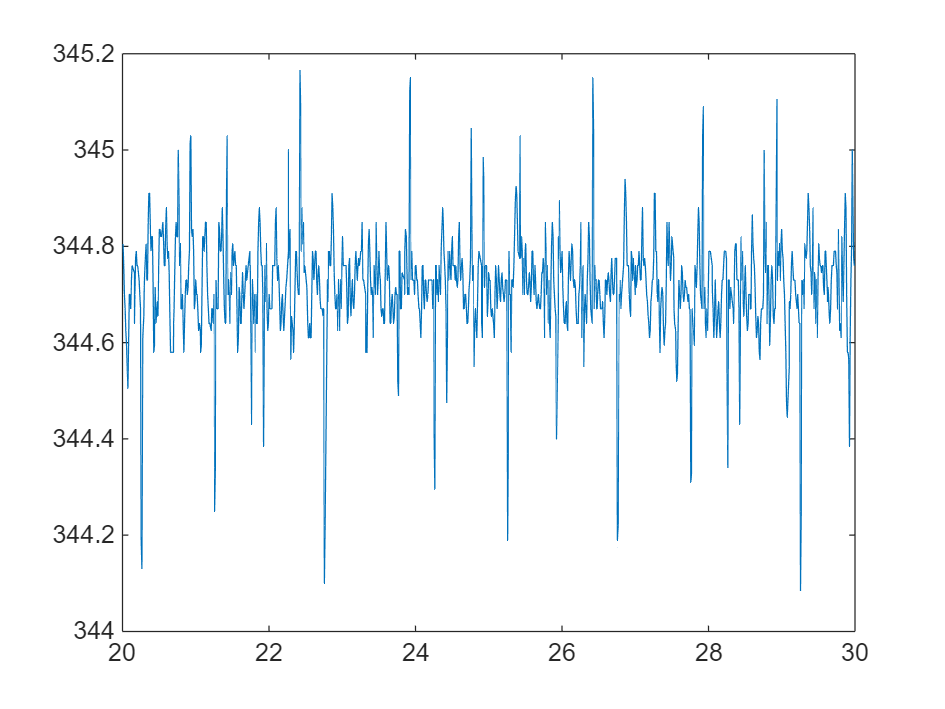

ts = 0.0096

std_ts = 0.0034

fs = 103.9663

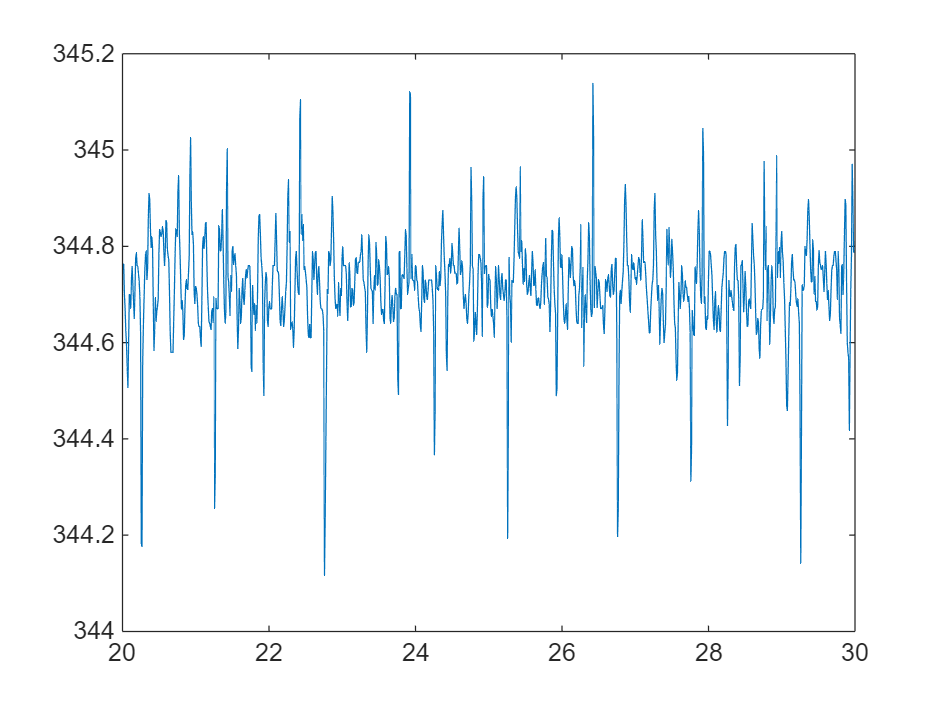

clc
clear
close all

voltage = 2:0.5:5.5;

data2plot = [];
data2compare = cell(1,length(voltage));

for i = 1:length(voltage)

    % acc_file = strcat("acc_2mm_",num2str(voltage(i)),"V_lg.txt");
    % acc_file = strcat('acc_',num2str(volrage(i)),'wk_sync.txt');

    % raw = readtable(name);
    %
    % time = table2array(raw(:,"Var1"));
    % time = time - time(1);
    %
    % raw_reading = table2array(raw(:,2:4));
    %
    % raw_acc = table2array(raw(:,5:7));
    %
    % raw_mag = table2array(raw(:,8));
    %


    %% read acc data
    % Open the file for reading
    fid = fopen(acc_file, 'r');
    if fid == -1
        error('File cannot be opened.');
    end

    % Initialize arrays for valid data
    timeSecs = [];
    value1  = [];
    value2  = [];

    % Define a regular expression pattern.
    % This pattern looks for:
    %  - One or more digits for hours, minutes, seconds, and milliseconds.
    %  - The literal " -> " between the time and the two numeric values.
    %  - Two floating-point numbers separated by a comma.
    pattern = '^(\d+):(\d+):(\d+):(\d+)\s*->\s*(-?\d+\.\d+),(-?\d+\.\d+)$';

    while ~feof(fid)
        tline = fgetl(fid);

        % Use regexp to see if the line matches the complete pattern.
        tokens = regexp(tline, pattern, 'tokens');

        if ~isempty(tokens)
            % Convert token strings to numbers.
            nums = cellfun(@str2double, tokens{1});
            h  = nums(1);
            m  = nums(2);
            s  = nums(3);
            ms = nums(4);
            v1 = nums(5);
            v2 = nums(6);

            % Convert the time into seconds.
            timeInSec = h*3600 + m*60 + s + ms/1000;



            timeInMs = timeInSec * 1000;

            % Append to our arrays
            timeSecs(end+1, 1) = timeInSec;
            value1(end+1, 1)  = v1;
            value2(end+1, 1)  = v2;
        end
        % If tokens is empty, the line is incomplete or doesn’t match the format.
        % In that case, it is automatically disregarded.
    end

    % Close the file
    fclose(fid);

    timeSecs = timeSecs - timeSecs(1);

    % Display the results (as a table for clarity)
    acc_data = table(timeSecs, value1, value2);

    time_idx = (timeSecs > 20) & (timeSecs < 30);
    time = timeSecs(time_idx);
    data = value2(time_idx);


    figure;
    plot(time,data)

    time_diff = time(2:end) - time(1:end-1);
    ts = mean(time_diff)
    std_ts = std(time_diff)
    fs = 1./ts

    rs_time = 0:ts:350;

    zero_ind = find(time_diff == 0);
    time(zero_ind) = [];
    data(zero_ind) = [];

    [~,idx_end] = min(abs(rs_time - time(end)));
    [~,idx_stt] = min(abs(rs_time - time(1)));


    rs_time  = rs_time(idx_stt:idx_end);
    rs_data = interp1(time,data,rs_time);

    rs_time(1) = [];
    rs_data(1) = [];

    rs_time(end) = [];
    rs_data(end) = [];

    figure;
    plot(rs_time,rs_data)

    % Low pass to try to remove noise

    cutoff_freq = 8;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
    lp_data= filtfilt(b, a, rs_data);

    figure;
    plot(rs_time,lp_data)

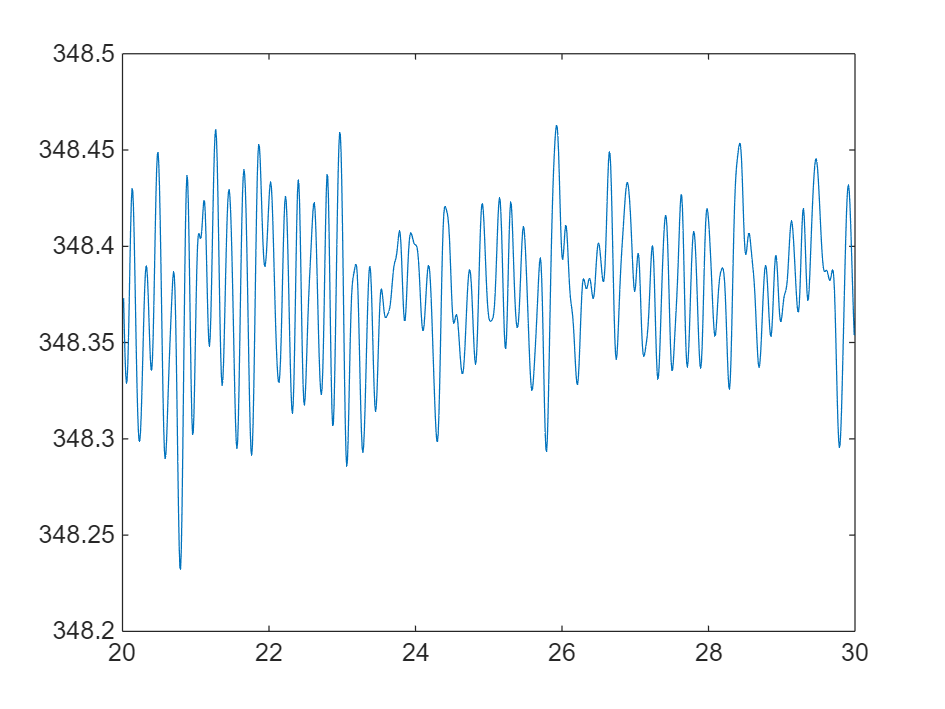

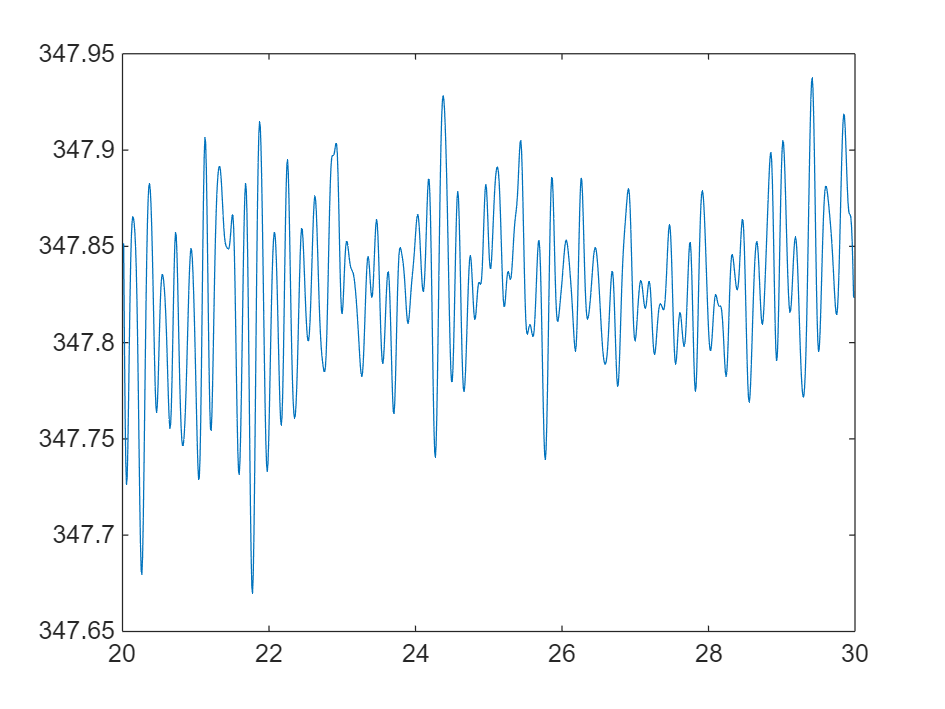

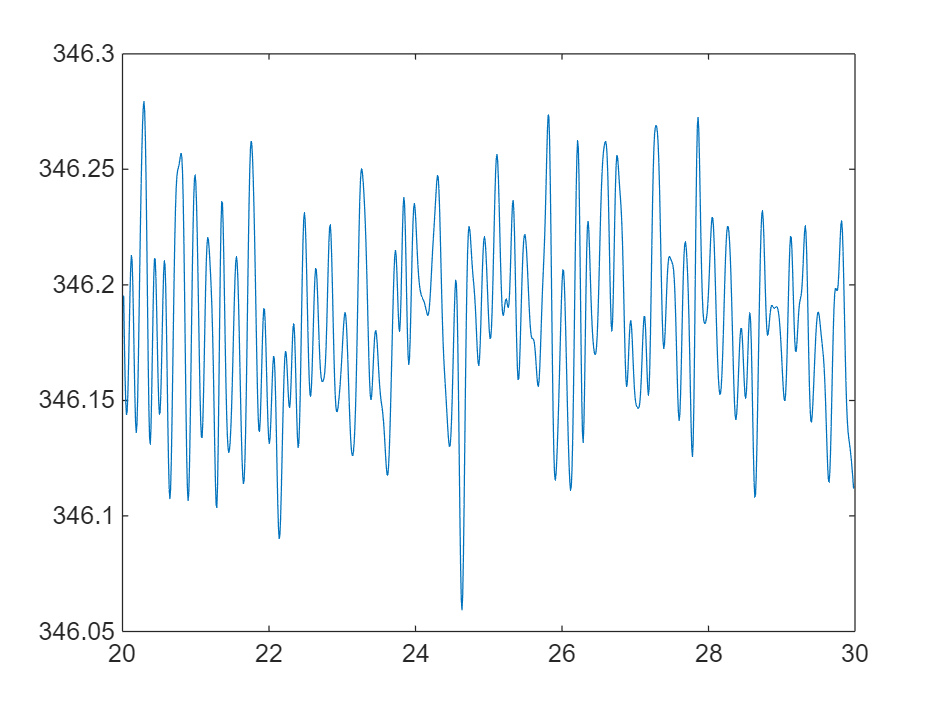

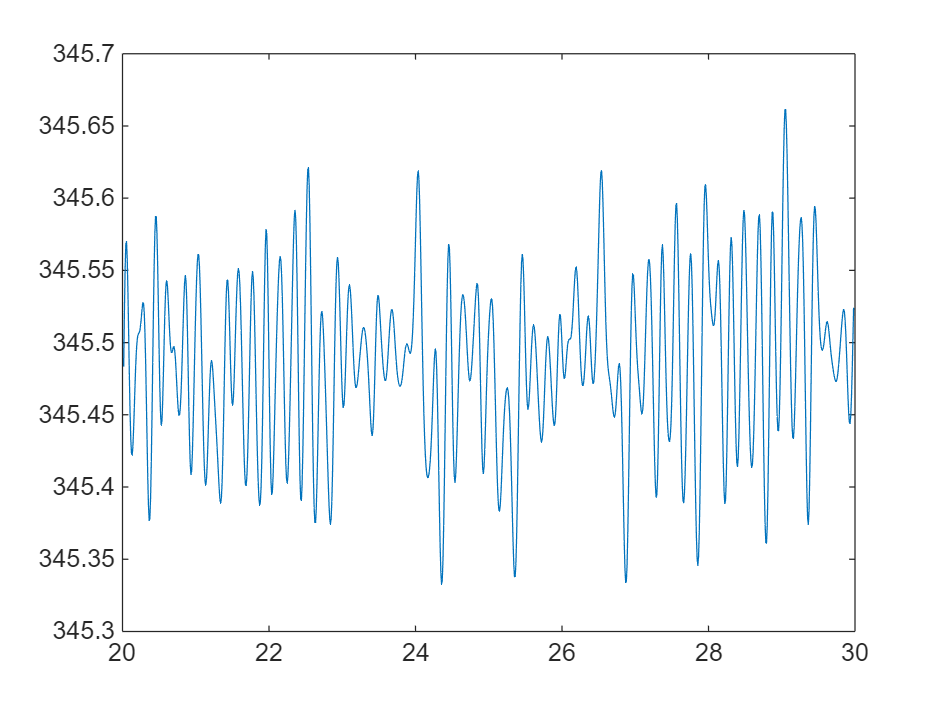

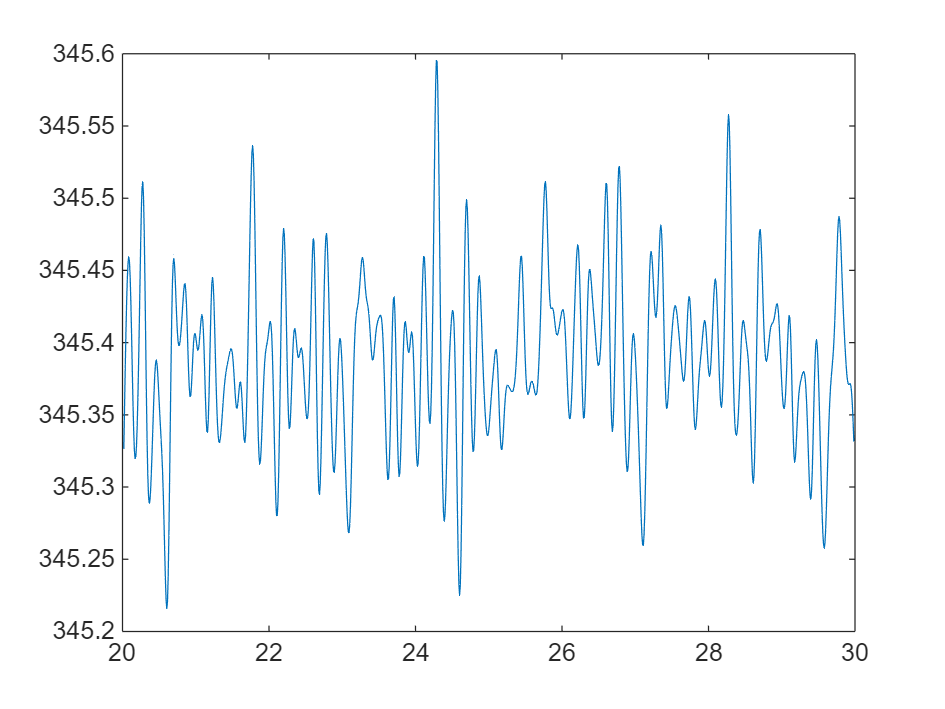

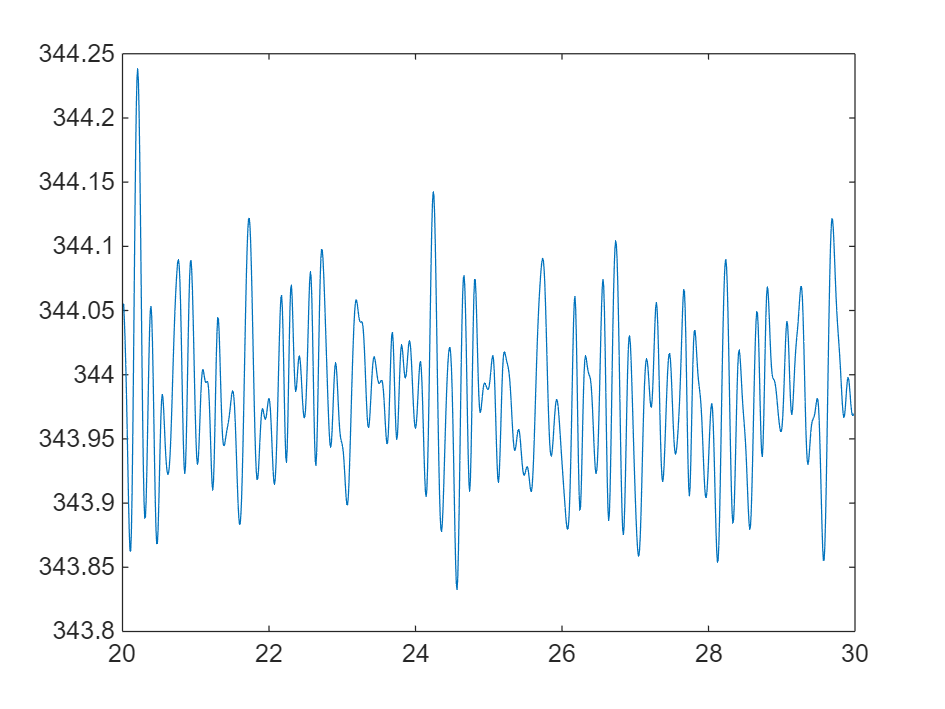

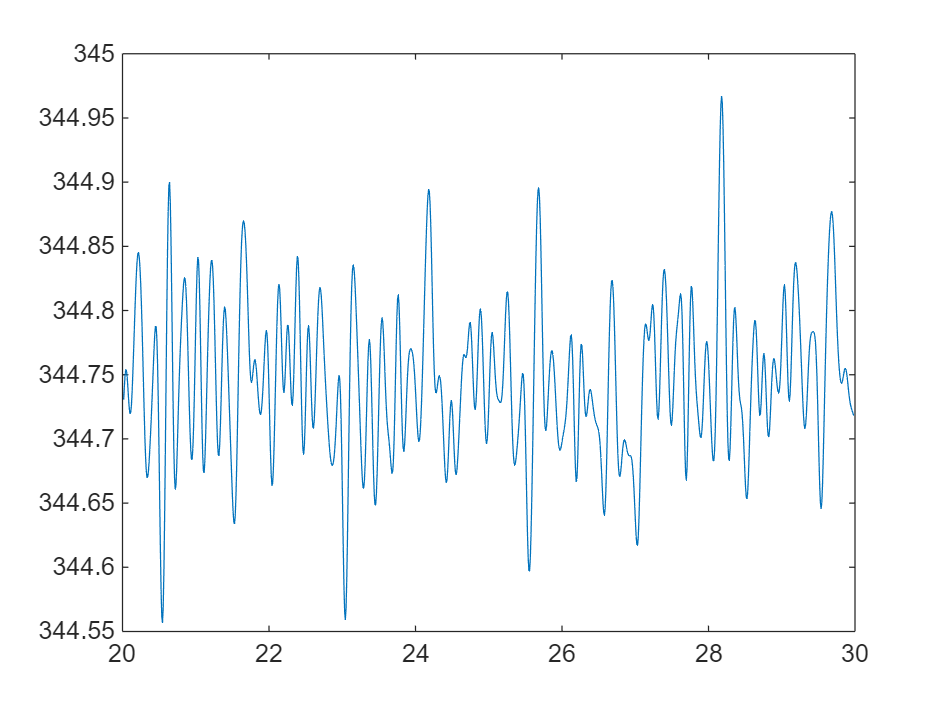

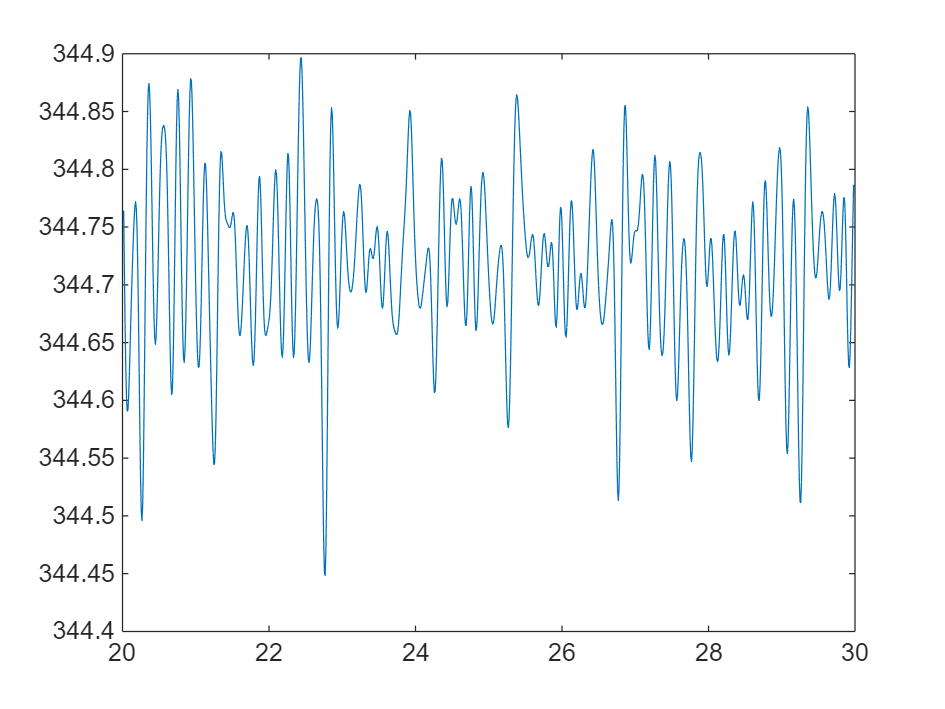

    % High pass to try to remove baseline

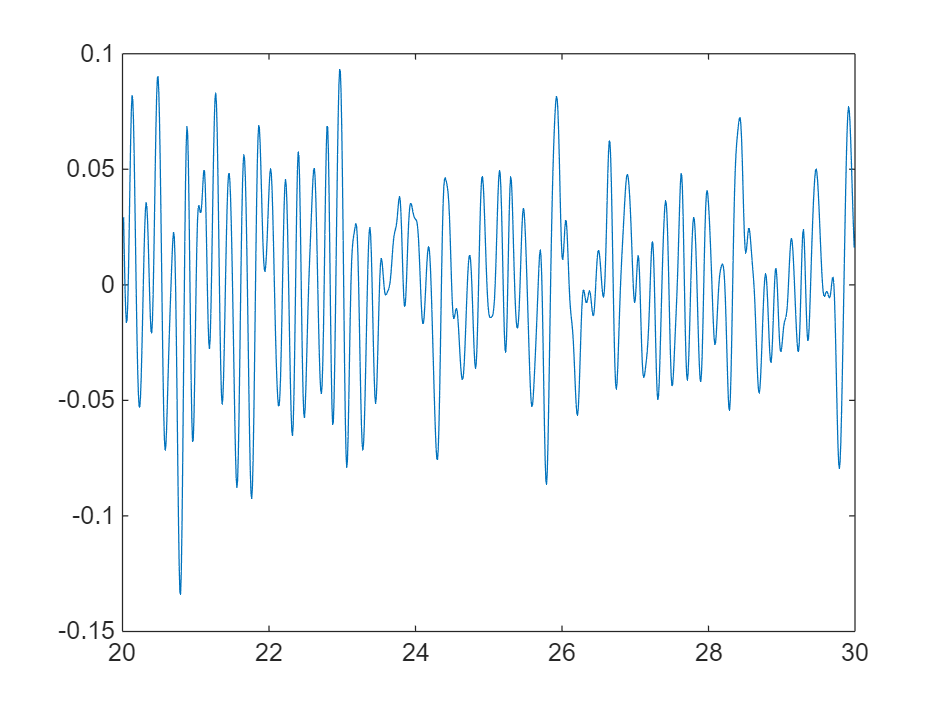

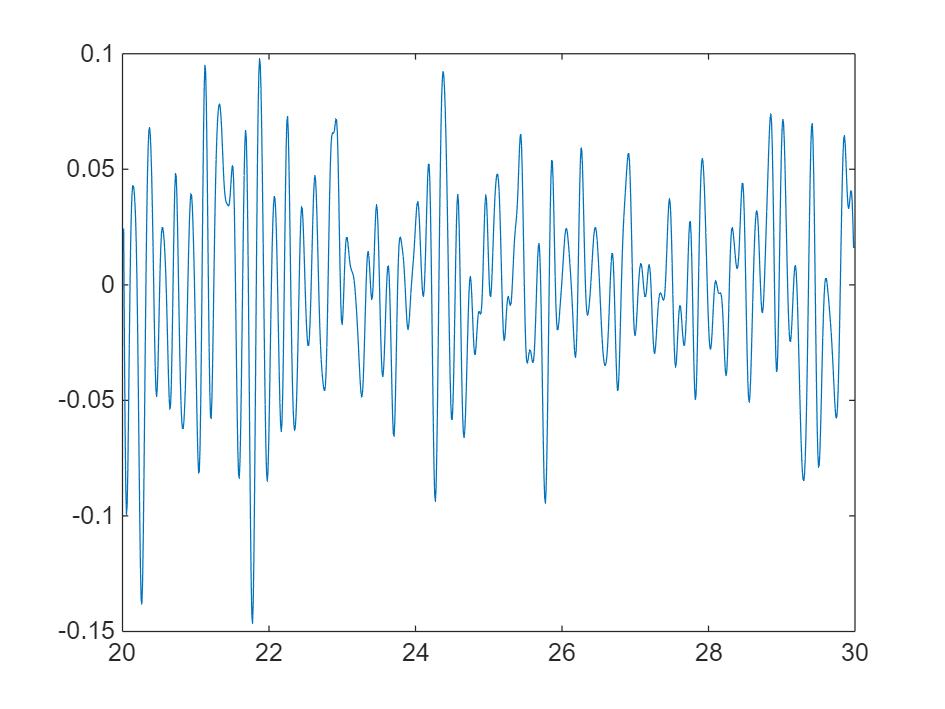

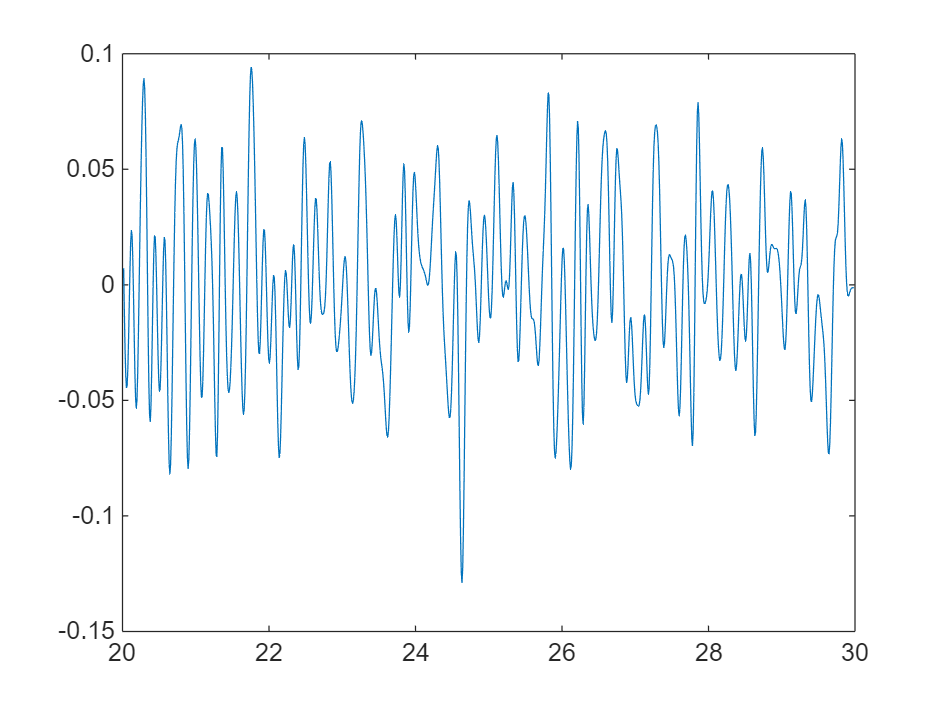

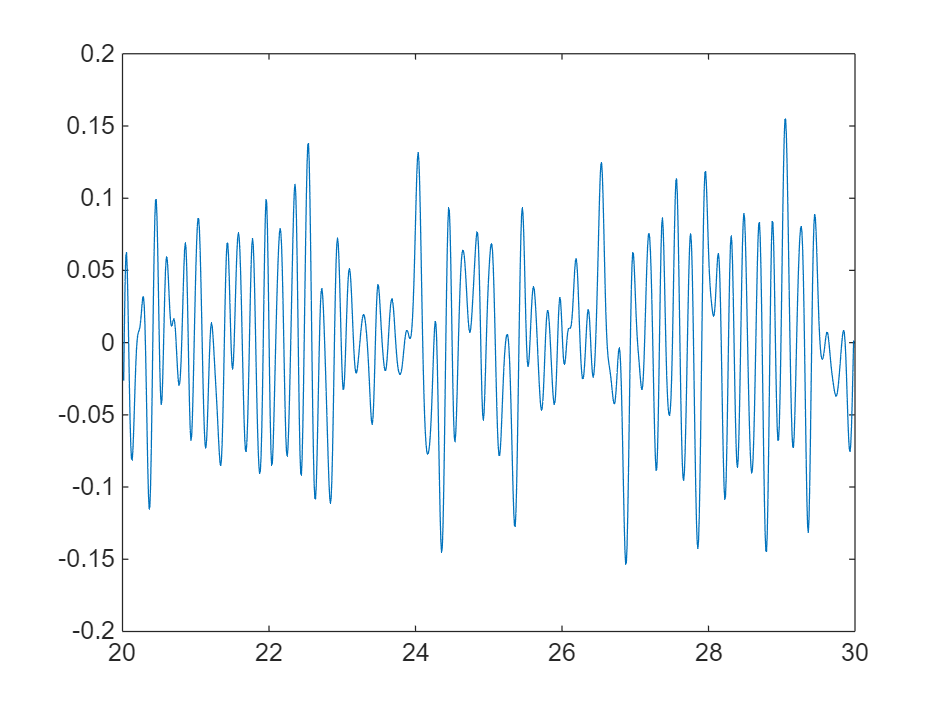

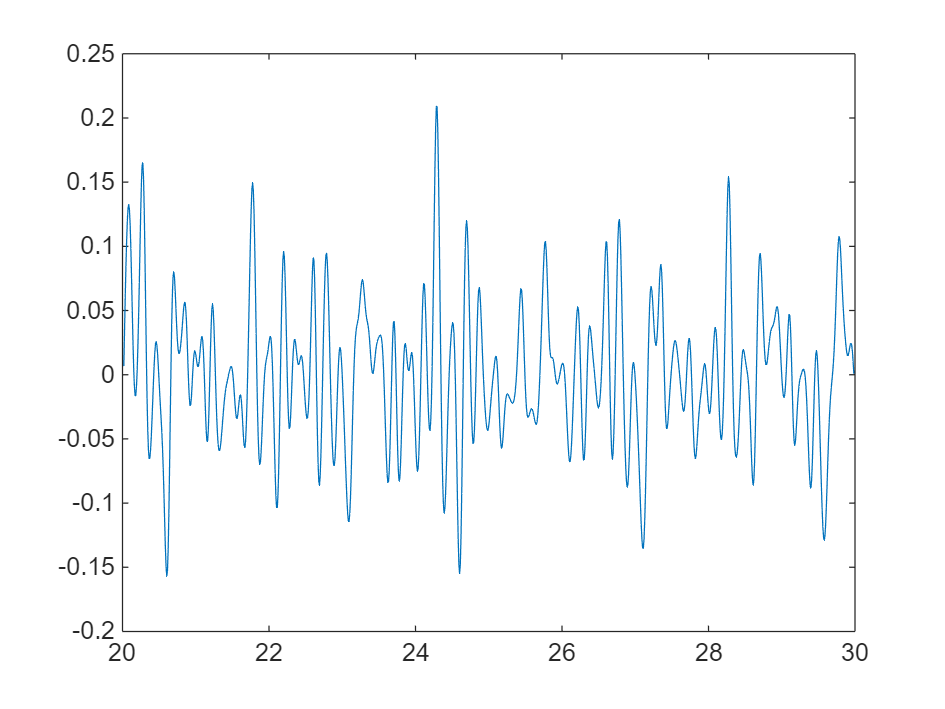

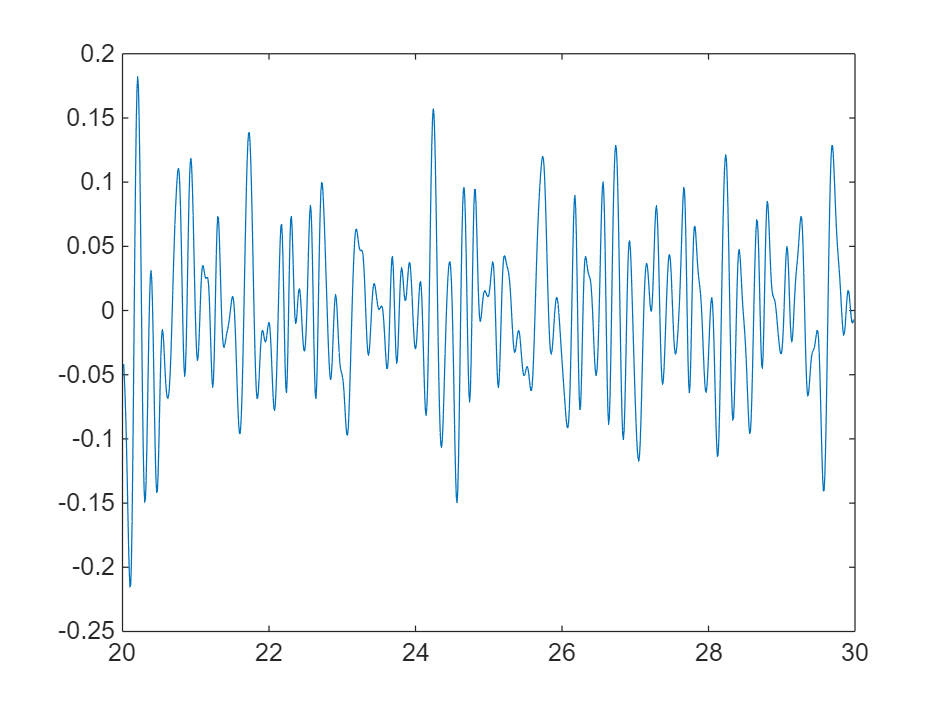

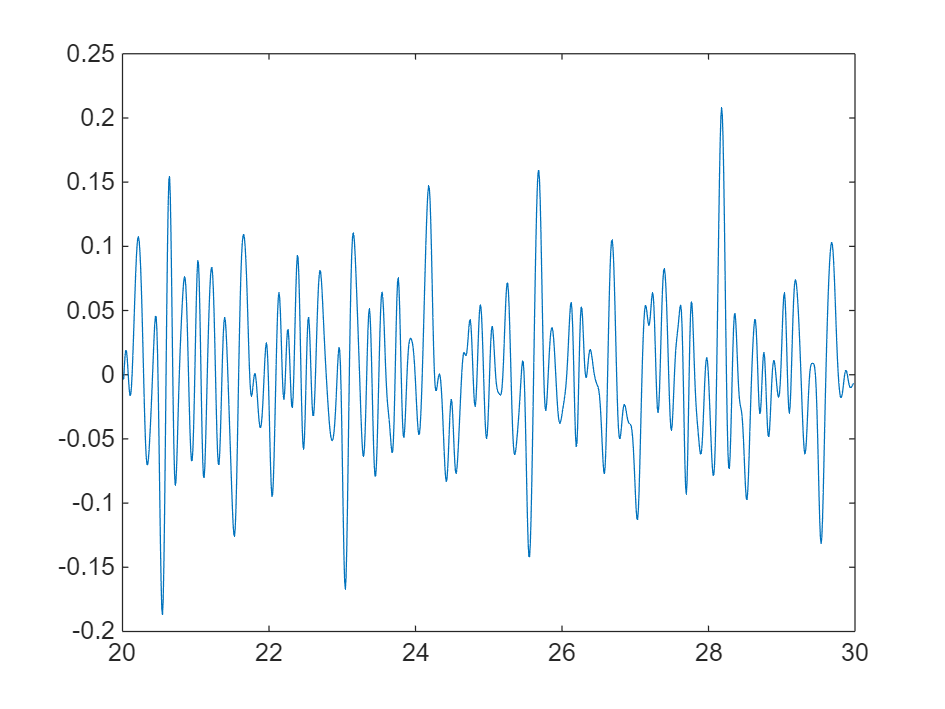

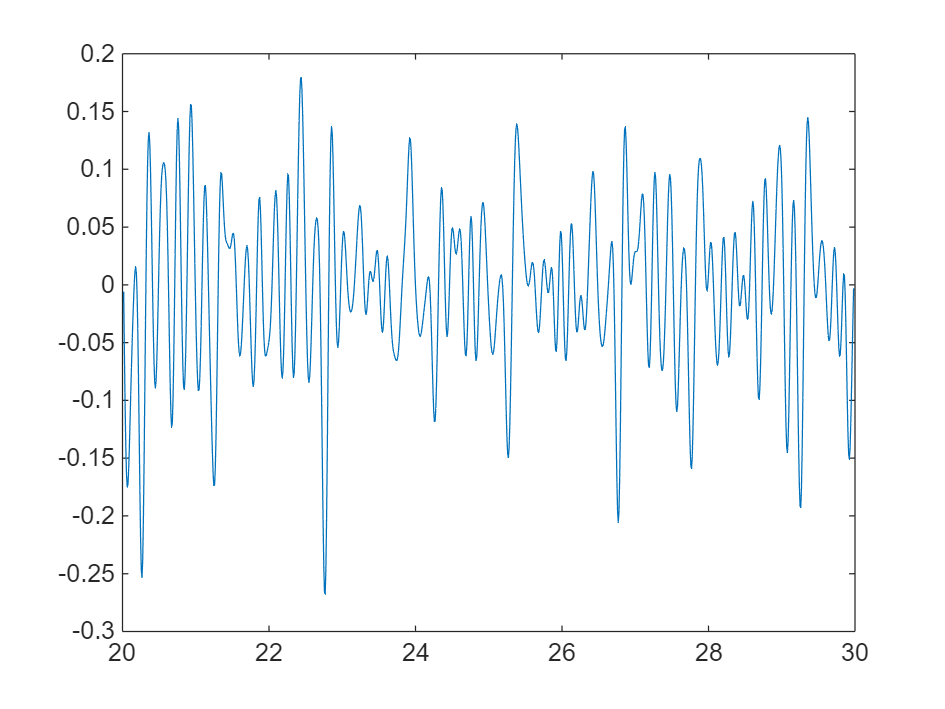


    cutoff_freq = 0.5;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
    hp_data= filtfilt(b, a, lp_data);

    figure;
    plot(rs_time,hp_data)


    % magnitude
    RMS = sqrt(mean(hp_data.^2))

    % p2p
    [pk_vals, pk_locs] = findpeaks(hp_data, rs_time,'MinPeakProminence', 0.1);
    [tr_vals_neg, tr_locs] = findpeaks(-hp_data, rs_time,'MinPeakProminence', 0.1);
    tr_vals = -tr_vals_neg;

    if tr_locs(1) < pk_locs(1)
        tr_locs(1) = []; tr_vals(1) = [];
    end

    N = min(numel(pk_locs), numel(tr_locs));
    pk_locs = pk_locs(1:N);
    pk_vals = pk_vals(1:N);
    tr_locs = tr_locs(1:N);
    tr_vals = tr_vals(1:N);

    p2p = pk_vals - tr_vals;
    mean_p2p = mean(p2p)
    std_p2p = std(p2p)

    data2save = [voltage(i),RMS,mean_p2p,std_p2p];
    data2plot = [data2plot;data2save];
    data2compare{i} = p2p;

end

RMS = 0.0370

mean_p2p = 0.1419

std_p2p = 0.0282

RMS = 0.0398

mean_p2p = 0.1409

std_p2p = 0.0308

RMS = 0.0368

mean_p2p = 0.1437

std_p2p = 0.0223

RMS = 0.0567

mean_p2p = 0.1820

std_p2p = 0.0428

RMS = 0.0551

mean_p2p = 0.1739

std_p2p = 0.0590

RMS = 0.0592

mean_p2p = 0.1752

std_p2p = 0.0481

RMS = 0.0565

mean_p2p = 0.1799

std_p2p = 0.0466

RMS = 0.0702

mean_p2p = 0.2051

std_p2p = 0.0592

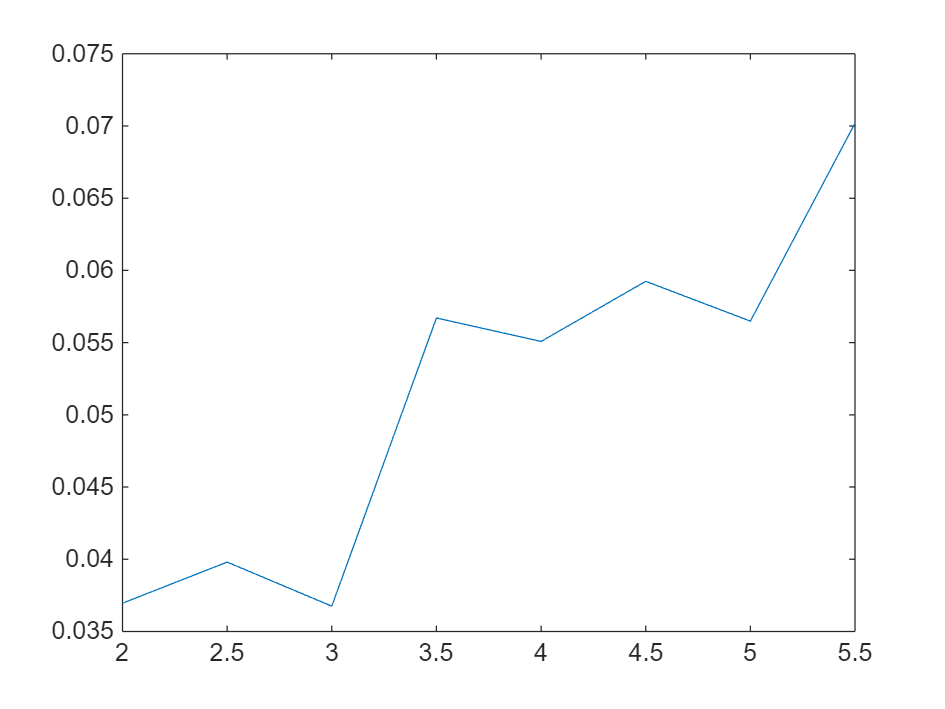

figure;
plot(data2plot(:,1),data2plot(:,2))

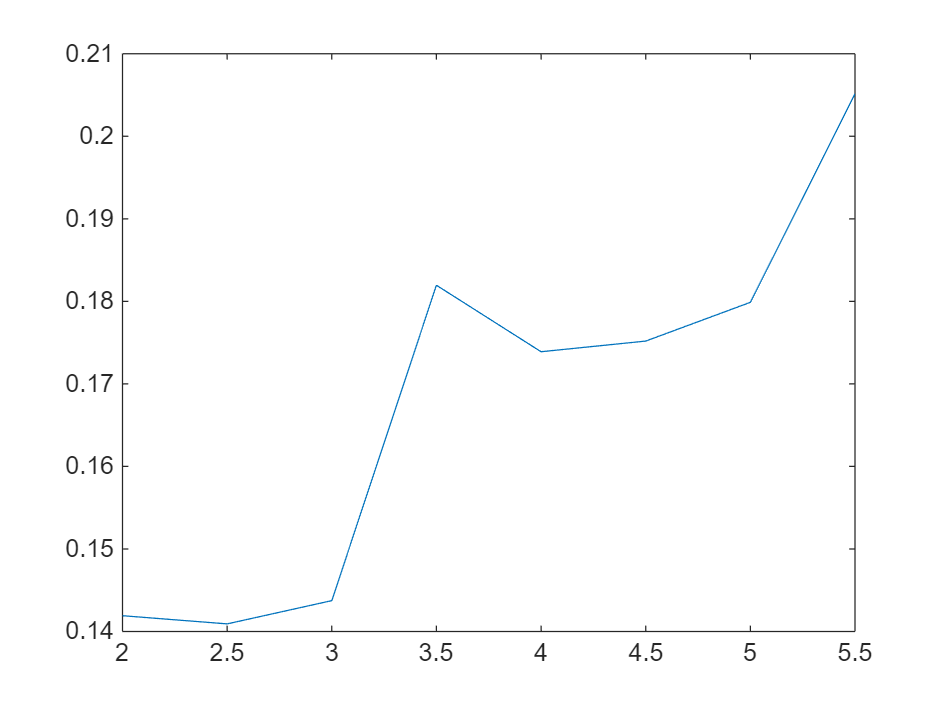

figure;
plot(data2plot(:,1),data2plot(:,3))

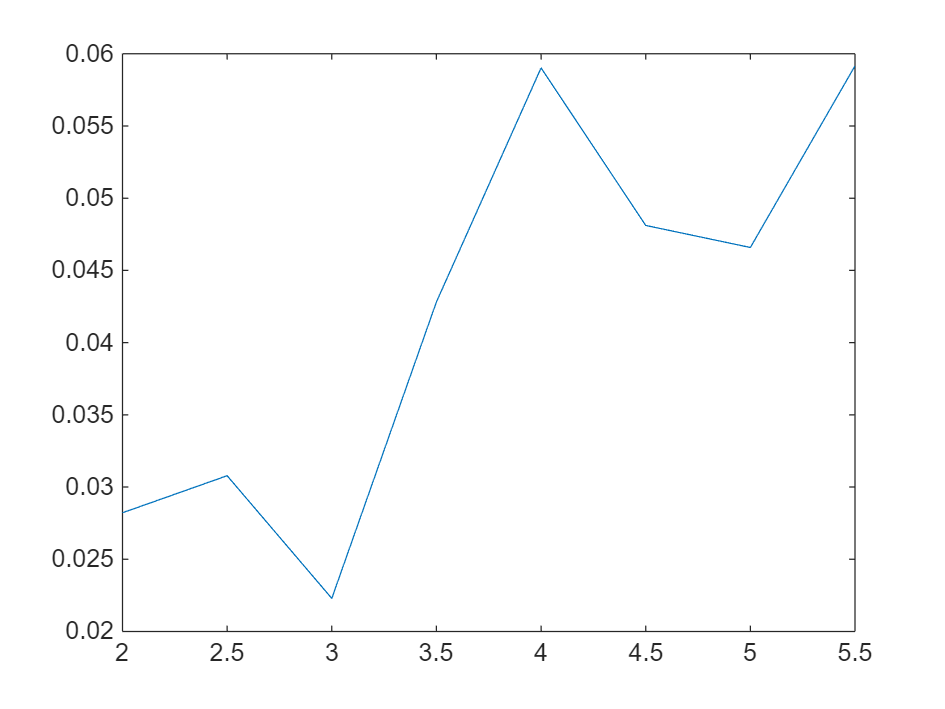

figure;
plot(data2plot(:,1),data2plot(:,4))